%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 对比一步高斯牛顿和多步高斯牛顿；随点数的影响
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 数据准备
%------------------------------
% 旋转矩阵
R_true=[0.689673028293550	0.423447870703166	0.587403621746887
        0.176155229057263	0.688715772969376	-0.703306419236294
        -0.702367745073895	0.588525687510876	0.400396136119796];
% 平移矢量
t_true = [2;3;4];

% 数据大小
num = [10,30,90,270,810,1000];

for n = 1:length(num)
    n
    
    % 生成俯仰角 [-10°, 10°] 转换为弧度
    elevation_angles = deg2rad(-10 + 20*rand(1, num(1,n)));
    % 生成方位角 [-30°, 30°]
    azimuth_angles = (-pi/6) + (pi/3) * rand(1, num(1,n));
    % 生成距离 [0, 5] 米
    d_true = 6 * rand(1, num(n));
    
    p_s = [];
    % 生成 p_s
    p_s(1,:)= (d_true .* cos(elevation_angles) .* cos(azimuth_angles));
    p_s(2,:)= (d_true .* cos(elevation_angles) .* sin(azimuth_angles));
    p_s(3,:)= (d_true .* sin(elevation_angles))';
    
    p_si = [];
    % 生成 p_si
    p_si(1,:)= d_true .* cos(azimuth_angles);
    p_si(2,:)= d_true .* sin(azimuth_angles);
    
    
    % 生成 p_w
    p_w = R_true*p_s+t_true;


n = 1

n = 2

n = 3

n = 4

n = 5

n = 6


    M = 1000;


    error_t = [0 0 0 0 0 0];
    error_R = [0 0 0 0 0 0];
    
    error_t_tan = [0 0 0 0 0 0];
    error_R_tan = [0 0 0 0 0 0];
    
    for j = 1:M
        %----------------------------------
        % 生成噪声数据 加在theta上
        % 噪声的标准差
        stdVar_noise_d = 0.001;
        stdVar_noise_theta = 0.001;
        
        d_noise = d_true + stdVar_noise_d*randn(1, num(n));
        
        noise_on_theta = stdVar_noise_theta*randn(1, num(n));
        theta_noise =  azimuth_angles + noise_on_theta;
        
%         p_si_noise =[];
%         p_si_noise(1,:)= d_noise .* cos(theta_noise);
%         p_si_noise(2,:)= d_noise .* sin(theta_noise);
        
        %----------------------------------
        % 生成噪声数据 加在theta上、
        tan_theta = tan(azimuth_angles);
        tan_theta_noise = tan_theta + noise_on_theta;
        
        theta_noise_tan= atan(tan_theta_noise);
        cos_theta_noise_tan = cos(theta_noise_tan);
        sin_theta_noise_tan = sin(theta_noise_tan);
        p_si_noise_tan = [d_noise.*cos_theta_noise_tan;d_noise.*sin_theta_noise_tan];

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 估计 R 和 t
%         [R,t] = two_step_algorihtm(p_w,p_si_noise,stdVar_noise_d,stdVar_noise_theta);
        
        % 先 对t进行GN
%         [R_tan,t_tan] = two_step_algorihtm_tGN(p_w,p_si_noise_tan,stdVar_noise_d,stdVar_noise_theta);
        % 不先 对t进行GN
        [R_tan,t_tan] = two_step_algorihtm(p_w,p_si_noise_tan,stdVar_noise_d,stdVar_noise_theta);
    
  
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %进行高斯牛顿迭代
    
        e_1 = [1 0 0]';
        e_2 = [0 1 0]';
    
    
        t_est_noise = t_tan;
        R_est_noise = R_tan;
        for k = 1:6
            t_est_noise = t_est_noise;
%             R_est_noise = R_est_noise;

            R_est_noise = R_est_noise;

            error_t(1,k) = error_t(1,k)+norm(t_est_noise-t_true)^2;

            s_R = rotm2eul(R_true'* R_est_noise,'XYZ');
            error_R(1,k) = error_R(1,k)+norm(s_R)^2;

            

             % 高斯牛顿优化
            e_1 = [1 0 0]';
            e_2 = [0 1 0]';
            I = eye(3);
        
            u_i = p_w-t_est_noise;
        
            %残差
            Residuals_R= zeros(2*num(n),1);
            f_1_residual = ((d_noise - vecnorm(u_i))/stdVar_noise_d)';
            f_2_residual = (tan_theta_noise - e_2'*R_est_noise'*(u_i)./(e_1'*R_est_noise'*(u_i)))./stdVar_noise_theta;
            
            Residuals_R((1:2:end)) = f_1_residual;
            Residuals_R((2:2:end)) = f_2_residual;
        
            J_phi = -[0,0,0;
                 0,0,1;
                 0,-1,0;
                 0,0,-1;
                 0,0,0;
                 1,0,0;
                 0,1,0;
                 -1,0,0;
                 0,0,0];
            R_est_noise_T = R_est_noise';
            vec_R = R_est_noise_T(:); 
        
        
            ukronR_2 = kron(u_i'*R_est_noise, I);
            g_2 = e_2'*R_est_noise'*u_i;
            h_2 = e_1'*R_est_noise'*u_i;
        
            % 初始化雅可比矩阵
            J_R_2 = zeros(2 * num(n), 6);
        
            % 更新 J_R 的奇数行
            J_R_2(1:2:end, 4:6) = (u_i ./ vecnorm(u_i) / stdVar_noise_d)';
        %     % 更新 J_R 的偶数行
            h_g_result = (h_2' .* e_2' - g_2' .* e_1');
        
            for i = 1:num(n)
                J_R_2(2*i,1:3) = -h_g_result(i,:)*ukronR_2(3*i-2:3*i,:)*J_phi./h_2(:,i)^2./stdVar_noise_theta;
            end
        
        % %     J_R_2(2:2:end, 1:3) = ((g_2' .* e_1') - (h_2' .* e_2')).* ukronR_2./ (h_2.^2 .* stdVar_noise_theta_est);
            J_R_2(2:2:end, 4:6) = (( h_g_result * R_est_noise')' ./ (h_2.^2 .* stdVar_noise_theta))';
        %t_first=t_est_noise_Gau;
        temp_result = [0;0;0;t_est_noise] - inv(J_R_2'*J_R_2)*J_R_2'*Residuals_R;
    
        t_est_noise = temp_result(4:6);
        s_new = temp_result(1:3);
        s_matrix = [0,-s_new(3),s_new(2);
                        s_new(3),0,-s_new(1);
                        -s_new(2),s_new(1),0];
        
           
       % R_first=R_est_noise_new;
        R_est_noise = R_est_noise*expm(s_matrix);
    
            
    
    
    
        end
        [crlb_R,crlb_t] = Calculate_CRLB(p_w,R_true,t_true,stdVar_noise_d,stdVar_noise_theta);


        CRLB_t_x(n,:) = sqrt(crlb_t);
        CRLB_R_x(n,:) = sqrt(crlb_R);


        Error_t(n,:) = sqrt(error_t/M);
        Error_R(n,:) = sqrt(error_R/M);
    
    
    %     Error_t_tan(n,:) = sqrt(error_t/M);
    %     Error_R_tan(n,:) = sqrt(error_R_tan/M);
    end

end







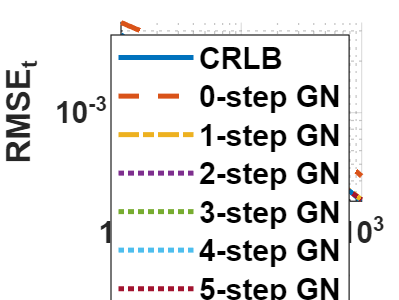

% Var_noise_base_x = stdVar_noise;
figure
grid on 
hold on;

loglog(num,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);

loglog(num,Error_t(:,1),'--','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_t(:,2),'-.','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_t(:,3),':','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_t(:,4),':','LineWidth', 2,'MarkerSize', 5);
loglog(num,Error_t(:,5),':','LineWidth', 2,'MarkerSize', 5);
loglog(num,Error_t(:,6),':','LineWidth', 2,'MarkerSize', 5);


legend('CRLB','0-step GN','1-step GN','2-step GN','3-step GN','4-step GN','5-step GN','FontSize', 12, 'FontWeight', 'bold');
xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_t','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

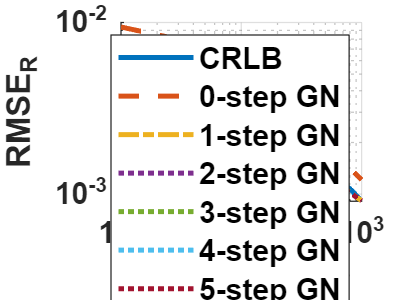

% Var_noise_base_x = stdVar_noise;
figure
grid on 
hold on;
loglog(num,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);
loglog(num,Error_R(:,1),'--','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_R(:,2),'-.','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_R(:,3),':','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_R(:,4),':','LineWidth', 2,'MarkerSize', 5);
loglog(num,Error_R(:,5),':','LineWidth', 2,'MarkerSize', 5);
loglog(num,Error_R(:,6),':','LineWidth', 2,'MarkerSize', 5);

legend('CRLB','0-step GN','1-step GN','2-step GN','3-step GN','4-step GN','5-step GN','FontSize', 12, 'FontWeight', 'bold');
xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE_R','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

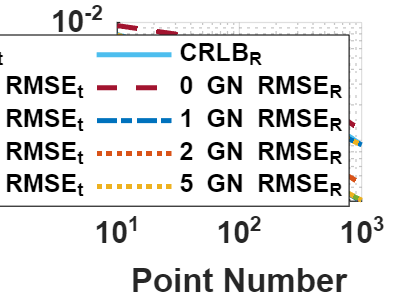

figure
grid on 
hold on;
loglog(num,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);

loglog(num,Error_t(:,1),'--','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_t(:,2),'-.','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_t(:,3),':','LineWidth', 2, 'MarkerSize', 5);
% loglog(num,Error_t(:,4),':','LineWidth', 2,'MarkerSize', 5);
% loglog(num,Error_t(:,5),':','LineWidth', 2,'MarkerSize', 5);
loglog(num,Error_t(:,6),':','LineWidth', 2,'MarkerSize', 5);

loglog(num,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);
loglog(num,Error_R(:,1),'--','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_R(:,2),'-.','LineWidth', 2, 'MarkerSize', 5);
loglog(num,Error_R(:,3),':','LineWidth', 2, 'MarkerSize', 5);
% loglog(num,Error_R(:,4),':','LineWidth', 2,'MarkerSize', 5);
% loglog(num,Error_R(:,5),':','LineWidth', 2,'MarkerSize', 5);
loglog(num,Error_R(:,6),':','LineWidth', 2,'MarkerSize', 5);

% legend('CRLB_t','0-step GN RMSE_t','1-step GN RMSE_t','2-step GN RMSE_t','5-step GN RMSE_t','CRLB_R','0-step GN RMSE_R','1-step GN RMSE_R','2-step GN RMSE_R','5-step GN RMSE_R','FontSize', 10, 'FontWeight', 'bold','NumColumns', 2);
legend('CRLB_t','0 GN RMSE_t','1 GN RMSE_t','2 GN RMSE_t','5 GN RMSE_t','CRLB_R','0 GN RMSE_R','1 GN RMSE_R','2 GN RMSE_R','5 GN RMSE_R','FontSize', 10, 'FontWeight', 'bold','NumColumns', 2);
% legend('CRLB_t','0-step GN RMSE_t','1-step GN RMSE_t','2-step GN RMSE_t','5-step GN RMSE_t','CRLB_R','RMSE_R','RMSE_R','RMSE_R','RMSE_R','FontSize', 10, 'FontWeight', 'bold','NumColumns', 2);
xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

% % Var_noise_base_x = stdVar_noise;
% figure
% grid on 
% hold on;
% loglog(num,Error_t(:,1),'--','LineWidth', 2,'Marker', '+', 'MarkerSize', 5);
% loglog(num,Error_t(:,2),'-.','LineWidth', 2,'Marker', 'v', 'MarkerSize', 5);
% loglog(num,Error_t(:,3),':','LineWidth', 2,'Marker', '>', 'MarkerSize', 5);
% loglog(num,Error_t(:,4),':','LineWidth', 2,'Marker', 'square', 'MarkerSize', 5);
% loglog(num,Error_t(:,5),':','LineWidth', 2,'Marker', 'o', 'MarkerSize', 5);
% loglog(num,Error_t(:,6),':','LineWidth', 2,'Marker', '*', 'MarkerSize', 5);
% 
% legend('0 step GN','1 step GN','2 step GN','3 step GN','4 step GN','5 step GN','FontSize', 12, 'FontWeight', 'bold');
% xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
% ylabel('RMSE_t','FontSize', 12, 'FontWeight', 'bold');
% set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');

% % Var_noise_base_x = stdVar_noise;
% figure
% grid on 
% hold on;
% loglog(num,Error_R(:,1),'--','LineWidth', 2,'Marker', '+', 'MarkerSize', 5);
% loglog(num,Error_R(:,2),'-.','LineWidth', 2,'Marker', 'v', 'MarkerSize', 5);
% loglog(num,Error_R(:,3),':','LineWidth', 2,'Marker', '>', 'MarkerSize', 5);
% loglog(num,Error_R(:,4),':','LineWidth', 2,'Marker', 'square', 'MarkerSize', 5);
% loglog(num,Error_R(:,5),':','LineWidth', 2,'Marker', 'o', 'MarkerSize', 5);
% loglog(num,Error_R(:,6),':','LineWidth', 2,'Marker', '*', 'MarkerSize', 5);
% 
% legend('0 step GN','1 step GN','2 step GN','3 step GN','4 step GN','5 step GN','FontSize', 12, 'FontWeight', 'bold');
% xlabel('Point Number','FontSize', 12, 'FontWeight', 'bold');
% ylabel('RMSE_R','FontSize', 12, 'FontWeight', 'bold');
% set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');